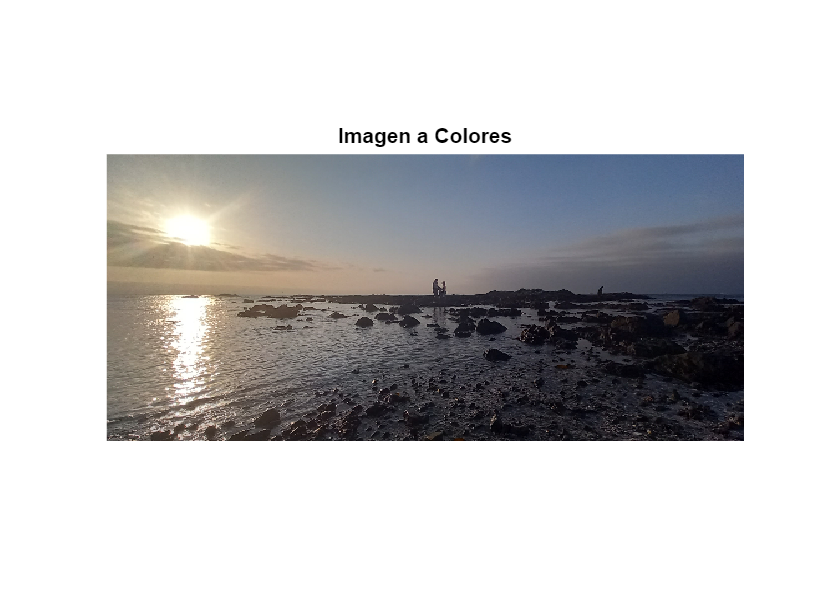

% 0.- Muestra imagenes originales
% Leer una imagen RGB de muestra (por ejemplo, peppers.png)
RGB1 = imread('imagenes/ilo.jpg');
% Mostrar la imagen en color verdadero utilizando imshow
imshow(RGB1);
title('Imagen a Colores');

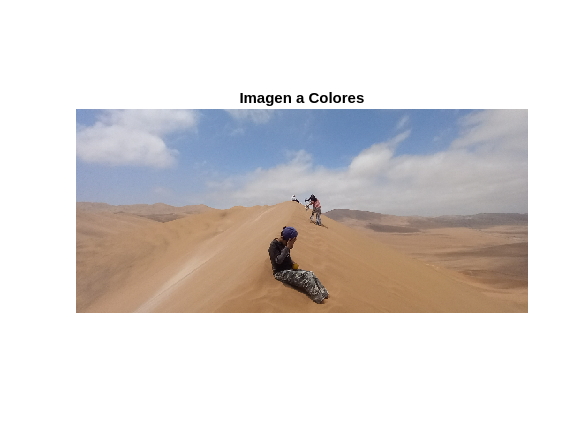


RGB2 = imread('imagenes/desierto.jpg');
% Mostrar la imagen en color verdadero utilizando imshow
imshow(RGB2);
title('Imagen a Colores');

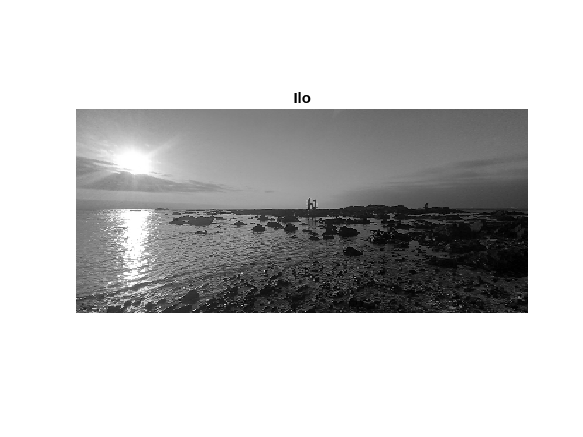


% 1. Cargar una imagen en forma matricial
imagen = imread('imagenes/ilo.jpg');
imagen = rgb2gray(imagen); % Convertir a escala de grises
figure, imshow(imagen), title('Ilo');

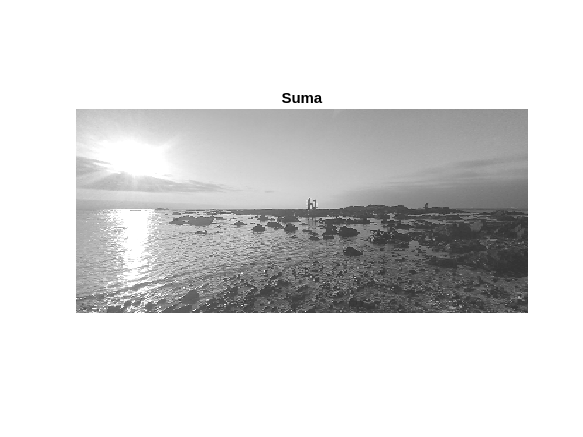


% 2. Operaciones matriciales básicas
% Suma: aumentar el brillo
suma = imagen + 50;

% Resta: disminuir el brillo
resta = imagen - 50;

% Multiplicación: aumentar el contraste
multiplicacion = imagen * 1.5;

% Mostrar las imágenes resultantes
figure, imshow(suma), title('Suma');

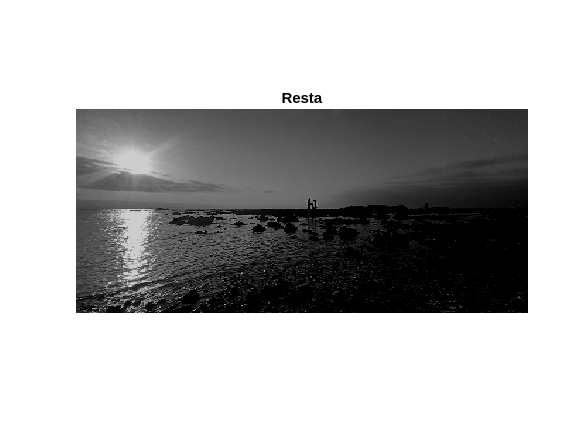

figure, imshow(resta), title('Resta');

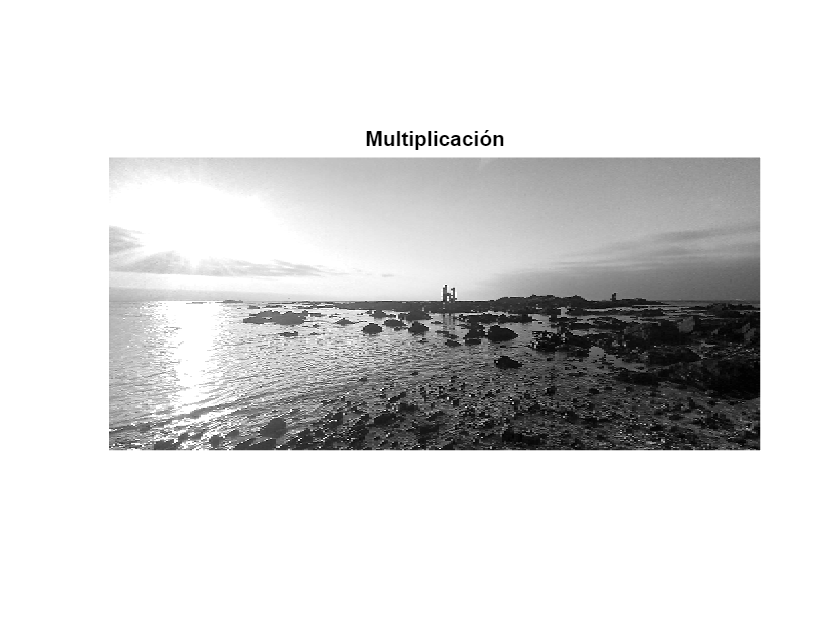

figure, imshow(multiplicacion), title('Multiplicación');

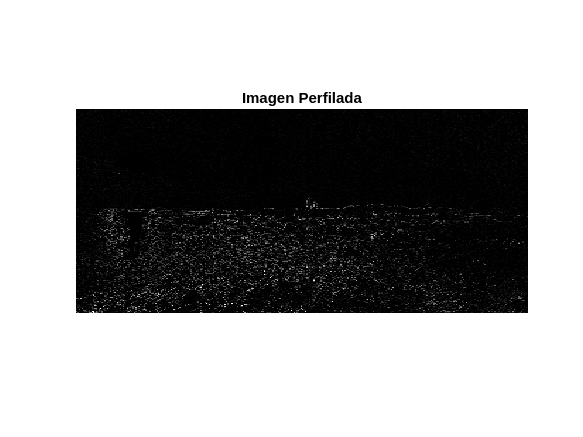


% 3. Definir una matriz para perfilado (detección de bordes)
filtro_perfilado = [0 -2 0;  -2 8  -2; 0 -2 0];
%imagen_perfilada = imfilter(double(imagen), filtro_perfilado); % Suponiendo que 'imagen' es una matriz de escala de grises

% Pre-allocar la matriz de salida para mejorar la eficiencia
[filas, columnas] = size(imagen);
imagen_perfilada = zeros(filas, columnas);

% Aplicar el filtro de perfilado usando un bucle for
for i = 2:filas-1
    for j = 2:columnas-1
        % Extracción de una submatriz de 3x3 alrededor del píxel
        submatriz = double(imagen(i-1:i+1, j-1:j+1));
        % Multiplicación elemento a elemento y suma para obtener el valor perfilado
        valor_perfilado = sum(sum(submatriz .* filtro_perfilado));
        % Asignar el valor calculado al píxel correspondiente en imagen_perfilada
        imagen_perfilada(i, j) = valor_perfilado;
    end
end

% Convertir la matriz de salida al tipo de datos original
imagen_perfilada = uint8(imagen_perfilada);

% Mostrar la imagen perfilada
imshow(imagen_perfilada);
title('Imagen Perfilada');

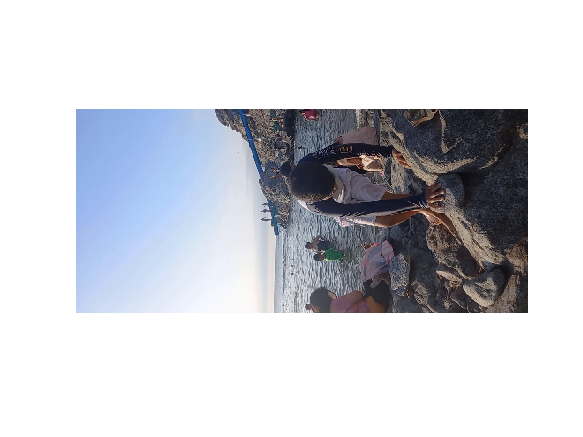


% 4. Superposición de imágenes
imagen2 = imread('imagenes/desierto.jpg');
imagen2 = rgb2gray(imagen2); % Convertir a escala de grises
superposicion = double(imagen) + 3 * double(imagen2);

% Mostrar la superposición de imágenes
figure, imshow(superposicion, []), title('Superposición de Imágenes');








 
% Lee el video
video = VideoReader('imagenes/video3.mp4');
% Mostrar los fotogramas del video
while hasFrame(video)
    vidFrame = readFrame(video);
    imshow(vidFrame);
    pause(1 / video.FrameRate);
end









% Asegúrate de que la carpeta para almacenar los frames exista
if ~isfolder('frames')
    mkdir frames
end

% Extrae 100 frames en formato jpg
num_frames = 100;
for i = 1:num_frames
    % Lee el siguiente frame del video
    frame = readFrame(video);
    
    % Guarda el frame como una imagen jpg en la carpeta 'frames'
    imwrite(frame, fullfile('frames', ['frame_' num2str(i) '.jpg']));
end

% Inicializa la matriz suma_imagenes
primer_frame = imread(fullfile('frames', 'frame_1.jpg'));
suma_imagenes = double(rgb2gray(primer_frame));

% Suma los 99 frames restantes
for i = 2:num_frames
    img_temp = imread(fullfile('frames', ['frame_' num2str(i) '.jpg']));
    img_temp = rgb2gray(img_temp);
    suma_imagenes = suma_imagenes + double(img_temp);
end

% Calcula el promedio
matriz_promedio = suma_imagenes / num_frames;

% Visualiza la matriz promedio
imshow(uint8(matriz_promedio));
title('Matriz Promedio de 100 Imágenes');






